clear all; clc; close all;

% Definizione dei parametri globali
global lunghezza_passo raggio_curva num_iterazioni punti direzioni contatore distanza_minima adjacency_matrix map

% Load map from a .mat file
data = load('map_straight_with_roundabout.mat');
% data = load('test/Files_mat/maps_5_1.mat');  % Sostituisci 'nome_file_mappa.mat' con il tuo percorso e nome del file

% Check available fields in 'data' structure
disp(fieldnames(data));

    {'map_straight_with_roundabout'}



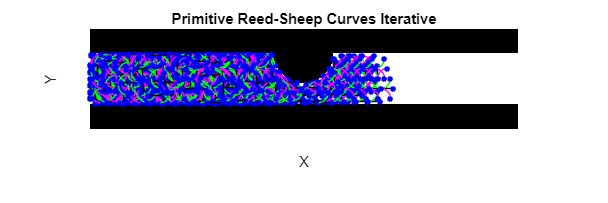


% Extract map from data structure
map = data.map_straight_with_roundabout';
% map = data.invertedImage;

% Definizione dei parametri
lunghezza_passo = 13; % Lunghezza del passo in avanti
raggio_curva = 10; % Raggio di curvatura per le curve a destra e sinistra
num_iterazioni = 20; % Numero di iterazioni
distanza_minima = 0.01; % Distanza minima tra i punti per considerare che coincidano

% Punto iniziale (centro degli assi)
punto_iniziale = [50, 40];

% Inizializzazione del vettore per i punti
punti = zeros(((num_iterazioni + 1)^3), 2);
punti(1, :) = punto_iniziale;

% Inizializzazione della matrice di adiacenza
adjacency_matrix = zeros(size(map));
adjacency_matrix(punto_iniziale(1), punto_iniziale(2)) = 1;  % Segna il punto iniziale come visitato

adjacency_matrix(map == 0) = 1; % Marca le celle con ostacoli come visitate

% Contatore dei punti
contatore = 1;

% Coda per i punti da esplorare
queue = [punto_iniziale, 0, 1]; % [x, y, angolo, iterazione]

% Plot initialization
figure;
imshow(map');
hold on;
% Plotting the start and goal points on the map
plot(punto_iniziale(1), punto_iniziale(2), 'ro', 'MarkerSize', 5, 'LineWidth', 2); % Start point (red)

% Avvio della ricorsione dal punto iniziale
while ~isempty(queue)
    % Estrai il punto corrente dalla coda
    punto_corrente = queue(1, 1:2);
    angolo_corrente = queue(1, 3);
    iterazione = queue(1, 4);
    queue(1, :) = [];  % Rimuovi l'elemento dalla coda

    % Calcola i nuovi punti e aggiungili alla coda se non visitati
    new_points = calculate_points(punto_corrente, angolo_corrente, iterazione);
    queue = [queue; new_points];  % Aggiungi i nuovi punti alla coda
end

% Aggiunta delle annotazioni finali
title('Primitive Reed-Sheep Curves Iterative');
xlabel('X');
ylabel('Y');
%legend('Linee in avanti', 'Punti successivi', 'Curve a destra', 'Curve a sinistra');
axis equal;
grid on;


% Funzione per calcolare i punti

function new_points = calculate_points(punto_corrente, angolo_corrente, iterazione)
    % Dichiarazione delle variabili globali
    global lunghezza_passo raggio_curva num_iterazioni punti contatore adjacency_matrix
    
    % Inizializzazione dei nuovi punti
    new_points = [];

    % Condizione di terminazione della ricorsione
    if iterazione > num_iterazioni
        return;
    end

    % Calcolo del punto successivo in avanti
    punto_avanti = round(punto_corrente + lunghezza_passo * [cos(angolo_corrente), sin(angolo_corrente)]);
    punto_finale_avanti = punto_avanti;

    % Centro della circonferenza per la curva a destra
    centro_destra = punto_corrente + raggio_curva * [cos(angolo_corrente - pi/2), sin(angolo_corrente - pi/2)];

    % Centro della circonferenza per la curva a sinistra
    centro_sinistra = punto_corrente + raggio_curva * [cos(angolo_corrente + pi/2), sin(angolo_corrente + pi/2)];

    % Angoli per generare i quarti di cerchio
    theta_destra = linspace(angolo_corrente + pi/2, angolo_corrente, 100);
    theta_sinistra = linspace(angolo_corrente - pi/2, angolo_corrente, 100);

    x_destra = centro_destra(1) + raggio_curva * cos(theta_destra);
    y_destra = centro_destra(2) + raggio_curva * sin(theta_destra);
    punto_finale_destra = round([x_destra(end), y_destra(end)]);

    x_sinistra = centro_sinistra(1) + raggio_curva * cos(theta_sinistra);
    y_sinistra = centro_sinistra(2) + raggio_curva * sin(theta_sinistra);
    punto_finale_sinistra = round([x_sinistra(end), y_sinistra(end)]);

    % Aggiunta dei punti e delle curve al plot solo se non coincidono con punti precedenti
    hold on;

    if is_within_bounds(punto_finale_avanti) && ~is_point_visited(punto_finale_avanti)
        if ~is_collision_avanti(punto_corrente, punto_finale_avanti)
            contatore = contatore + 1;
            punti(contatore, :) = punto_finale_avanti;
            adjacency_matrix(punto_finale_avanti(1), punto_finale_avanti(2)) = 1;  % Marca il punto come visitato
            plot([punto_corrente(1), punto_finale_avanti(1)], [punto_corrente(2), punto_finale_avanti(2)], 'k-', 'LineWidth', 0.5);
            plot(punto_finale_avanti(1), punto_finale_avanti(2), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_avanti, angolo_corrente, iterazione + 1];  % Aggiungi ai nuovi punti
        end
    end

    if is_within_bounds(punto_finale_destra) && ~is_point_visited(punto_finale_destra)
        if ~is_collision_curve(x_destra, y_destra)
            contatore = contatore + 1;
            punti(contatore, :) = punto_finale_destra;
            adjacency_matrix(punto_finale_destra(1), punto_finale_destra(2)) = 1;  % Marca il punto come visitato
            plot(x_destra, y_destra, 'g', 'LineWidth', 0.5);
            plot(x_destra(end), y_destra(end), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_destra, angolo_corrente - pi/2, iterazione + 1];  % Aggiungi ai nuovi punti
        end
    end

    if is_within_bounds(punto_finale_sinistra) && ~is_point_visited(punto_finale_sinistra)
        if ~is_collision_curve(x_sinistra, y_sinistra) 
            contatore = contatore + 1;
            punti(contatore, :) = punto_finale_sinistra;
            adjacency_matrix(punto_finale_sinistra(1), punto_finale_sinistra(2)) = 1;  % Marca il punto come visitato
            plot(x_sinistra, y_sinistra, 'm', 'LineWidth', 0.5);
            plot(x_sinistra(end), y_sinistra(end), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_sinistra, angolo_corrente + pi/2, iterazione + 1];  % Aggiungi ai nuovi punti
        end
    end
end

% Funzione per verificare se un punto è già stato visitato
function visited = is_point_visited(punto)
    global adjacency_matrix
    visited = false;
    if adjacency_matrix(punto(1), punto(2)) == 1
        visited = true;
    end
end

% Funzione per verificare se un punto è all'interno dei limiti della matrice
function within_bounds = is_within_bounds(punto)
    global adjacency_matrix
    within_bounds = punto(1) > 0 && punto(2) > 0 && punto(1) <= size(adjacency_matrix, 1) && punto(2) <= size(adjacency_matrix, 2);
end

% Funzione per verificare se un punto è all'interno dei limiti della matrice
function collision_avanti = is_collision_avanti(punto_corrente, punto_finale_avanti)
    global map

    collision_avanti = false;
    % disp(collision_avanti);
    % Calcola i punti equidistanti tra p_start e p_end
    x_points = round(linspace(punto_corrente(1), punto_finale_avanti(1), 300));
    y_points = round(linspace(punto_corrente(2), punto_finale_avanti(2), 300));
    for i = 2:(length(x_points)-1)
        if map(x_points(i), y_points(i)) == 0
            collision_avanti = true;
            break
        end
    end
    % disp(collision_avanti);
end

% Funzione per verificare se un punto è all'interno dei limiti della matrice
function collision_curve = is_collision_curve(x, y)
    global map

    collision_curve = false;
    % disp(collision_curve);
    for i = 2:(length(x)-1)
        if map(round(x(i)), round(y(i))) == 0
            collision_curve = true;
            break
        end
    end
    % disp(collision_curve);
end
